# Compresión 2D por descomposición SVD

## Cargamos la imagen original

% Leemos el mapa de bits que sale del microscopio
I = imread('../../tiltser_W.tif',6);

% Determinamos dimensiones de la imagen
nx = size(I,1); ny = size(I,2);

## Descomposición SVD y compresión

% Inicializamos la figura
figure(1), clf, subplot(1,4,1);
imagesc(I), axis off, colormap gray
title("STEM img")

% Descomponemos I aplicando SVD
tic;
[U,S,V] = svd(double(I));
disp(['SVD done. (' num2str(toc) 's)'])

SVD done. (0.011688s)


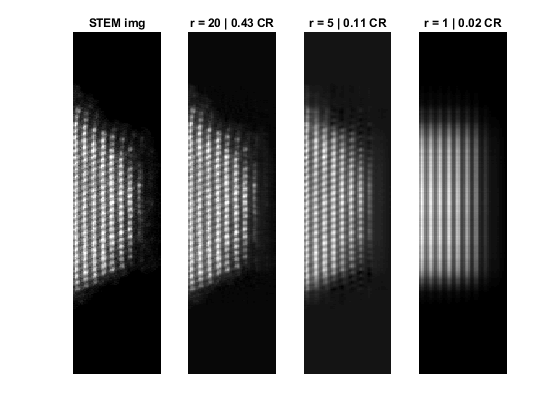


% Truncamos a r valores significativos
r_list = [20 5 1];
I_storage = uint16(zeros(nx,ny,length(r_list)));

i = 1;
for r = r_list
    % Seleccionamos los elementos con los que nos vamos a quedar
    Yap = U(:,1:r)*S(1:r,1:r)*V(:,1:r)';
    
    % Mostramos la imagen comprimisa junto a ratio de compresión
    subplot(1,4,i+1);
    imagesc(Yap), axis off
    title("r = " + num2str(r,"%d") + " | " + num2str(r*(nx+ny)/nx/ny,"%.2f CR"));
    
    % Almacenamos las imágenes
    I_storage(:,:,i) = Yap;

    i = i + 1;
end